Digital Signal Processing Lab (EE-384L)

# Assignment No. 2:   **Introduction to Sampling and Linear Time-Invariant Systems**

### Reg. No. :   **2016-EE-189**

## Task 1

**Statement:**

Sample a 15 second audio, at a sampling rate of 44100 samples per second, reading the given text. Then take the samples of this 15-second audio and turn it into a 10-second audio that has the entire message. You can do so by playing back the audio quickly to finish it within 10 seconds.

**Code (with Results):**

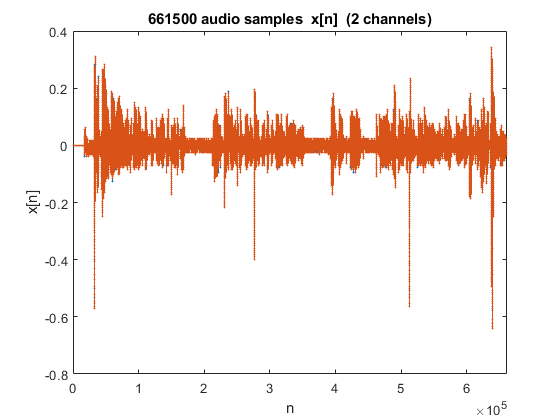

% task: record audio for 15 seconds at 44100 samples per second

% Sampling Frequency (samples per second)
Fs = 44100;

% [syntax] recorder = audiorecorder(Fs,nBits,NumChannels,ID)
recorder = audiorecorder(Fs, 8, 2, 1);

% set funtions to execute on recording start/end
recorder.StartFcn = 'disp(''Start speaking.'')';
recorder.StopFcn = 'disp(''End of recording.'')';

% record for 15 seconds, in blocking mode
% [syntax] recordblocking(recorderObj, length_seconds)
recordblocking(recorder, 15);

% get the recorded data, and plot it
rec = recorder.getaudiodata;
stem(rec, 'filled', 'MarkerSize', 1);
xlabel('n'); ylabel('x[n]'); 
xlim([0 length(rec)]);
title(strcat(num2str(length(rec)), ' audio samples  x[n]  (2 channels)'));


% save the audio data to a .wav file
filename = 'lab2.wav';
audiowrite(filename, rec, Fs);

This 15 second audio, sampled with Fs = 44100 samples/second, has a total of (15 × 44100 = ) 661500 samples. 

To fit the same audio into 10 seconds, it has to be played back at a rate of:


$$\frac{661500\;\textrm{samples}}{10\;\textrm{seconds}}=66150\;\textrm{samples}/\textrm{second}$$


Since this is just the playback rate provided to the DAC of the sound card, there is no loss of samples, rather the DAC is provided more number of samples (66150 per second, compared to previous 44100) per second to construct the time-domain signal. Hence, the DAC is still provided a total 661500 samples, but now within 10 seconds.

**Code (continued):**

% task: playback the audio, at a different sample rate, to fit within 10 seconds

% read audio data back from the created file
[x, Fs] = audioread(filename);

% calc. new sample rate for playback
duration = 10;              % 10 seconds
pb_sampleRate = length(x)/duration

pb_sampleRate = 66150


% [syntax] sound(seq,Fs,nBits)
sound(x, pb_sampleRate, 8);

Here, the array 'x' (length = 661500) itself does not have any notion of duration. But provided the (new) Sample-Rate of 66150 samples/second, the duration comes out to be $661500/66150=10\;\mathrm{seconds}\ldotp$ 

Hence, in this playback, the audio of the entire text-reading spans only 10 seconds, and the voice pitch has increased due to higher frequency of samples.

## Task 2

**Statement:**

Create an echo effect of the same voice recording you did in Task 1, by implementing the following system in MATLAB code:  $y\left(t\right)=x\left(t\right)+x\left(t-0\ldotp 5\right)$

To achieve this, produce a sampled version x[n − nd] of x(t). Then, add the resulting two sequences x[n] and x[n − nd] to get y[n] and convert it into y(t) using the sound command.

**Methodology**

The DT system to be implemented is x[n] + x[n - nd], where delay in samples 'nd' should correspond to a time delay of 0.5s for given Fs. At the sampling rate of 44100 samples/second, the number of samples in half a second would be, $44100/2=22050$ samples. 

Hence, the delay nd should be, ${\mathrm{n}}_{\mathrm{d}} =22050$.

**Code (with Results):**

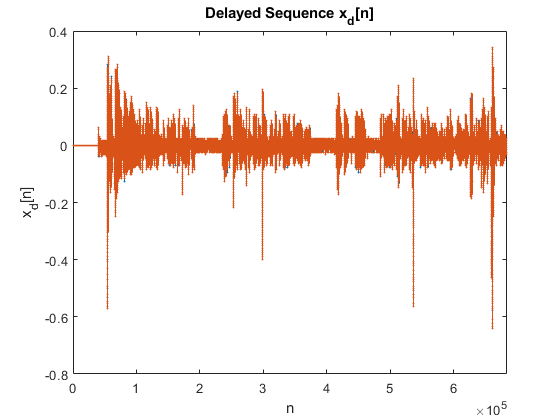

% task: generate an echo effect on the Task 1 voice recording (15s)

% first generate the delayed sequence
nd = 22050;                 % #samples delay to be added
% x[n] is a 661500 × 2 size matrix (2 channel audio)
% xd[n] matrix would have the size (661500+nd) × 2
xd = vertcat(zeros(nd, 2), x);

% plot the delayed sequence
stem(xd, 'filled', 'MarkerSize', 1);
xlabel('n'); ylabel('x_d[n]'); xlim([0 length(xd)]);
title('Delayed Sequence x_d[n]');

% pad zeros to the end of x[n] to match its dimensions with xd[n]
xp = vertcat(x, zeros(nd, 2));

% add (padded) x[n] and xd[n] to get the echo-effect signal y[n]
y = xp+xd;


% plot the resultant signal y[n]

*(Figure is on the next page.)*

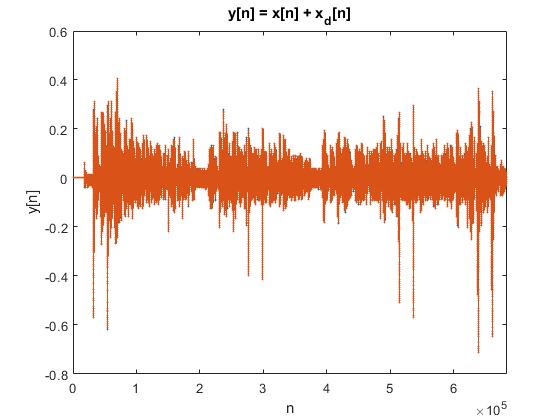

stem(y, 'filled', 'MarkerSize', 1);
xlabel('n'); ylabel('y[n]'); xlim([0 length(y)]);
title('y[n] = x[n] + x_d[n]');

% get and play y(t) using sound command
sound(y, Fs);

Since the audio has 2 channels, x[n] has 2 columns of 661500 samples. It is assumed that n lasts from 0 to 661500-1 for x[n]. 

To delay x[n] by nd (positive), a zero-matrix of size $\textrm{nd}\times 2$ is vertically concatenated to the beginning of x[n], resulting in xd[n] of size $\left(661500+\textrm{nd}\right)\times 2$.

y[n] is simply obtained by matrix-summation of x[n] and xd[n], after padding size $\textrm{nd}\times 2$ zero-matrix to the end of x[n] to match its matrix-dimensions with xd[n]. Resulting y[n] matrix has the size $\left(661500+\textrm{nd}\right)\times 2$.

Since x[n], being a stereo audio signal, has 2 channels, and because the audio is just assumed to start at n=0, 'sigshift' and 'sigadd' functions were not used for the respective delay/summation operations, and no n vector is maintained (for x[n] or xd[n]).

*All the discrete plots in the report (for x[n], xd[n], y[n]) show both the channels together (superimposed).*